## 構造パターンによる平均音速値に対する影響

figure;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_02_analyzePatternModel')
load('2018_08_02_aveSOS&steSOS')
[num_EMCLrate, num_pattern] = size(aveSOS);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;

subplot(2,2,1);
hold on;
xlabel('EMCL[%]');
ylabel('Average Speed of Sound[m/s]')
xlim([0 22])
x = [2 4 6 8 10 12 14 16 18 20];
for i = 1:num_pattern
    errorbar(x, aveSOS(x,i), 2*steSOS(x,i));
end
legend('case 1', 'case 2', 'case 3')
hold off;

addpath(genpath('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\codes'))
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\param')
load('param_2board.mat')
kgrid = makeGrid(param.grid.Nx, param.grid.dx, param.grid.Ny, param.grid.dy);

         Update codes to use the syntax kgrid = kWaveGrid(...).


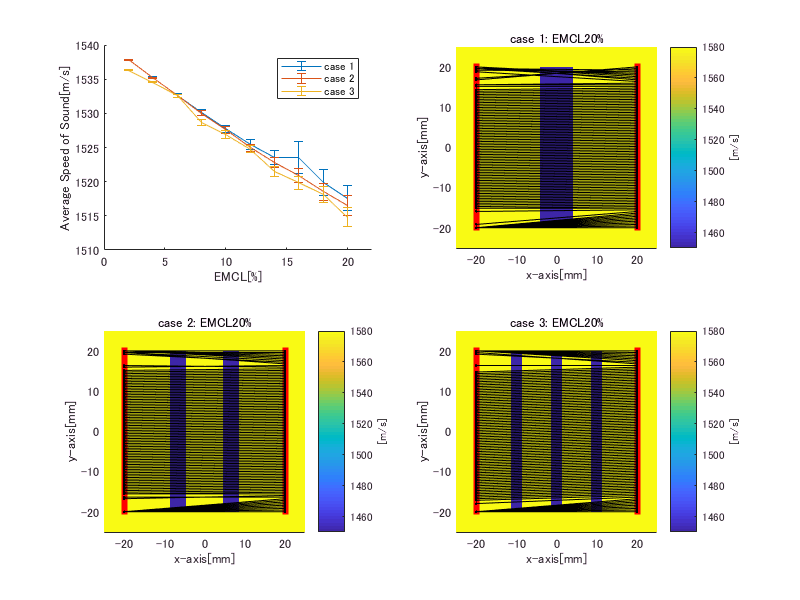

for j = 1:3
    subplot(2,2,j+1);
    hold on
    medium = makePatternMedium(1, param, 20, j, 0);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    [~,ind] = min(tof_cell(101:end,:,20,j));
    ind = ind+100;
    for i = 1:length(ind)
        plot([t_pos(2,i)*1000;t_pos(2,ind(i))*1000],[t_pos(1,i)*1000;t_pos(1,ind(i))*1000],'.-k','LineWidth',0.01);
    end
    xlabel('x-axis[mm]')
    ylabel('y-axis[mm]')
    myfilename = sprintf('case %d: EMCL20%%',j);
    title(myfilename);
    colorbar;
    caxis([1450 1580]);
    c = colorbar;
    c.Label.String = '[m/s]';
    hold off
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_02_analyzePatternModel')
myfilename = 'rEMCL2to20 & nEMCL1to3';
exportfig(myfilename,'png',[800,600]);

## 構造パターン間のRFデータ比較

figure;
for i = 1:3
    subplot(2,3,i);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_02_patternScatter');
    myfilename = sprintf('rEMCL20 & nEMCL%d', i);
    mytitle = sprintf('RFdata[case %d: EMCL20%%]',i)
    cd(myfilename)
    load('rfdata.mat')
    imagesc(rfdata(:,:,50),[-0.1 0.1]);
    title(mytitle);
    xlabel('Sensor Position');
    ylabel('Time Step');
    colorbar;
end

mytitle = 'RFdata[case 1: EMCL20%]'

mytitle = 'RFdata[case 2: EMCL20%]'

mytitle = 'RFdata[case 3: EMCL20%]'

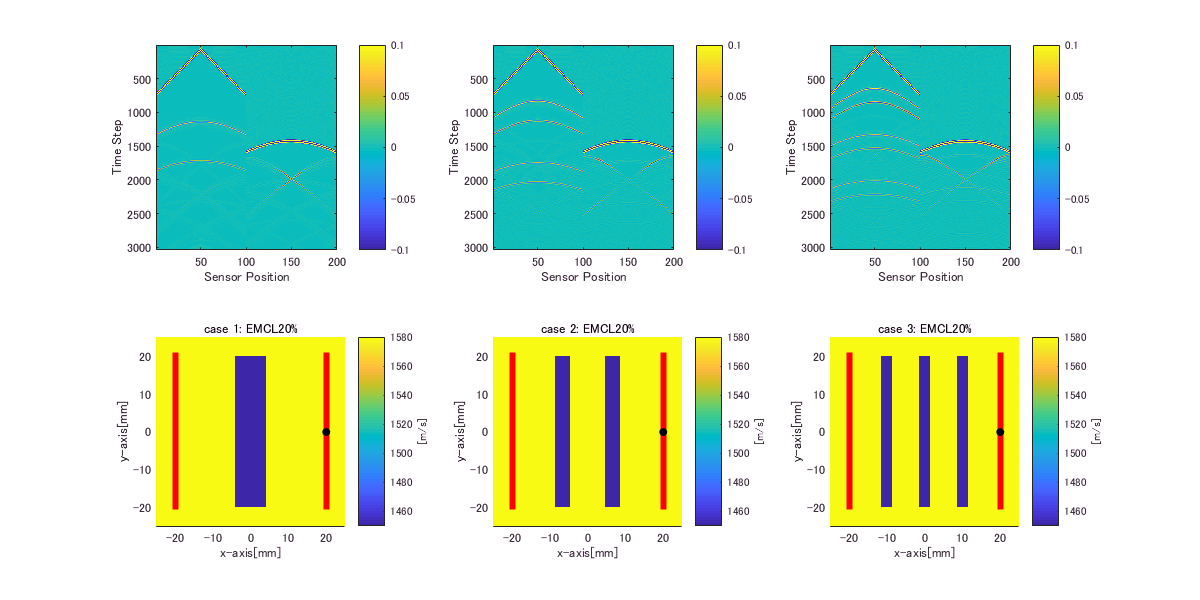

for j = 1:3
    subplot(2,3,j+3);
    hold on
    medium = makePatternMedium(1, param, 20, j, 0);
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    scatter(t_pos(2,50)*1000,t_pos(1,50)*1000,'ko','filled');
    xlabel('x-axis[mm]')
    ylabel('y-axis[mm]')
    myfilename = sprintf('case %d: EMCL20%%',j);
    title(myfilename);
    colorbar;
    caxis([1450 1580]);
    c = colorbar;
    c.Label.String = '[m/s]';
    hold off
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_02_analyzePatternModel')
myfilename = 'rfdata[rEMCL2to20 & nEMCL1to3]';
exportfig(myfilename,'png',[1200,600]);